# Lab 7 - Event selection optimization

Thomas Conaway

Lab Partners: Avi Soval, Jeff Jiang

clc; clear; close all;
% signal dataset is labelled higgs, background dataset is labeled "qcd"
% h5disp("higgs_100000_pt_1000_1200.h5");
% h5disp("qcd_100000_pt_1000_1200.h5");
signaldata1 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bgdata1 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

## Problem 1

Stacked histogram for the mass feature variable, normalized to expected yields of 50 for Higgs and 2000 for the QCD:

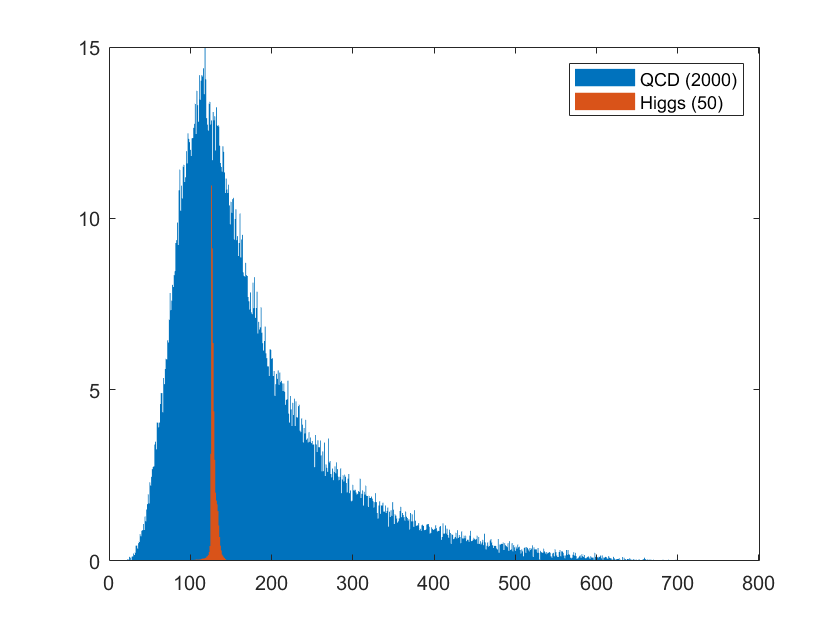

signal = signaldata1(4,:);
bg = bgdata1(4,:);
x = 0:1:800; % finer steps for bin size results in sharper Higgs peak
figure("Visible","off");
h = histogram(signal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
hold off;
f1 = figure();
figure(f1);
% can use the following to properly "stack" bars
% y = [h2.BinCounts;h.BinCounts];
% bar(h2.BinEdges(2:end),y.','stacked',"Edgecolor","none","BarWidth",1); 
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (2000)","Higgs (50)");
hold off;

Higgs distribution is very sharply peaked at 125 MeV. When collecting, we would see the combined QCD and Higgs distribution, with this jutting out. In the next lab (Lab 8) we can see this appear in our high luminosity data.

Using Poisson statistics for significance calculation (*do significance calculation using poisson with a mean of the expected value). I spoke with Olivia at the end of our last lab to try to clarify what exactly was meant by "mean of the expected value". I had originally thought the significance calculation would come from the data distribution that corresponds to the stacked histogram above, but this instead meant the expected values 2000, 50, and their sum 2050, which we use as the mean for our calculation.

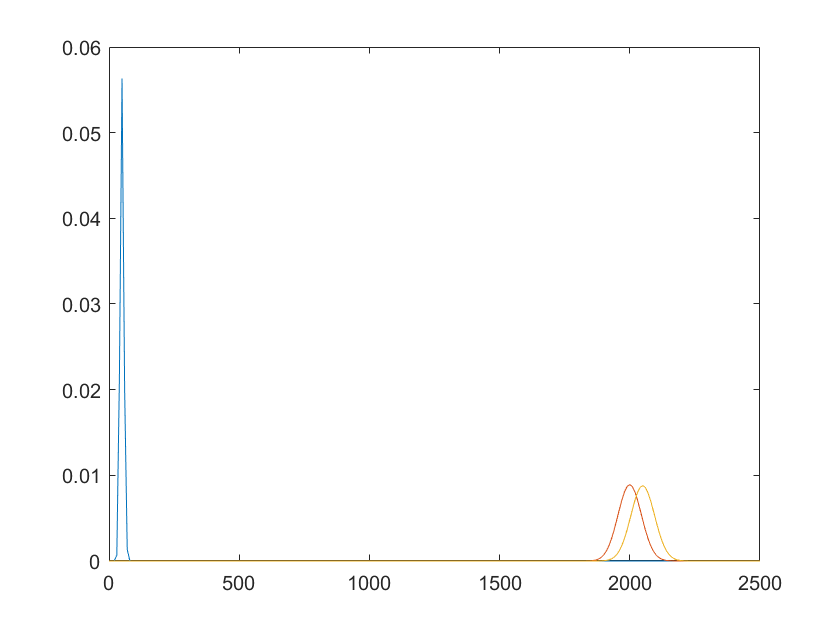

disthiggs = makedist("Poisson","lambda",50);
distqcd = makedist("Poisson","lambda",2000);
distcombo = makedist("Poisson","lambda",2050);
x = 0:10:2500;
plot(x,pdf(disthiggs,x));
hold on;
plot(x,pdf(distqcd,x));
plot(x,pdf(distcombo,x));
hold off;

Significance as I understand it should refer to the probability of background producing the event. It's not immediately clear what we should be looking for here. When we run this experiment we expect to see, for 2050 total events, 2000 background and 50 Higgs. Are we looking for the probability of the background producing 50 Higgs detections, or something else?

Significance calculation:

prob = cdf(distqcd,2050,'upper'); % this produces a value close to higgs/sqrtbg, but I don't know why
sigma1 = abs(norminv(prob))

sigma1 = 1.1282

% original significance calculation
prob2 = cdf(makedist("Poisson","lambda",118),125,'upper');
sigma2 = abs(norminv(prob2))

sigma2 = 0.6985

% some more experimentation
meanhiggs = mean(signal);
meanqcd = mean(bg);
% meancombo = mean([bg,signal]);
% meancombo2 = meanhiggs*(meanhiggs/(meanhiggs+meanqcd)) + meanqcd*(meanqcd/(meanhiggs+meanqcd))
sigma3 = abs(norminv(cdf("Poisson",meanhiggs,meanqcd)))

sigma3 = 4.0082

% abs(norminv(cdf("Poisson",meanhiggs,meancombo2)))

Comparison to $N_{\mathrm{Higgs}} \;/\sqrt{\;N_{\mathrm{QCD}} }$:

50/sqrt(2000)

ans = 1.1180

These two values should be equivalent. The purpose of this making this comparison is to show that this new expression can also be used to calculate significance.

## Problem 2

We will first try cutting below 100 and above 145, because this preserves almost all of the Higgs data while making significant cuts to the background.

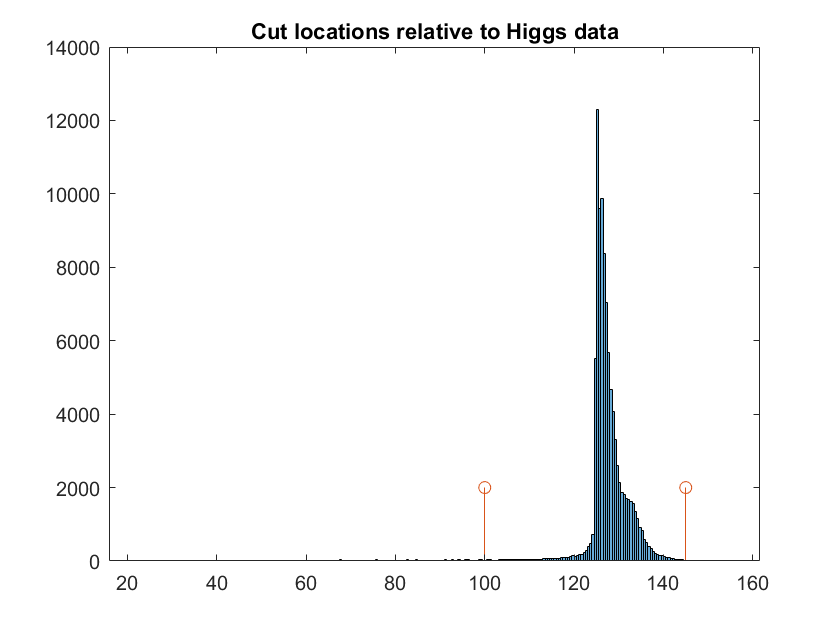

lowercut = 100;
uppercut = 145;
histogram(signal);
hold on;
stem([lowercut,uppercut],[2000,2000]);
title("Cut locations relative to Higgs data")
hold off;

% removing data that falls outside cuts
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
% re-normalizing the cut signal to the expected yields. Example: if we
% expect 50 Higgs and our cut removes half the area of their distribution, we now expect to now hold
% onto only 25 Higgs. The fraction of the data remaining multiplied the normalization factor will
% give us this because the un-normalized area of the histogram gives the
% total count, so a faction of the counts is a fraction of the area.
nhiggs = numel(cutsignal)/numel(signal)*50

nhiggs = 48.9905

nqcd = numel(cutbg)/numel(bg)*2000

nqcd = 573.8200

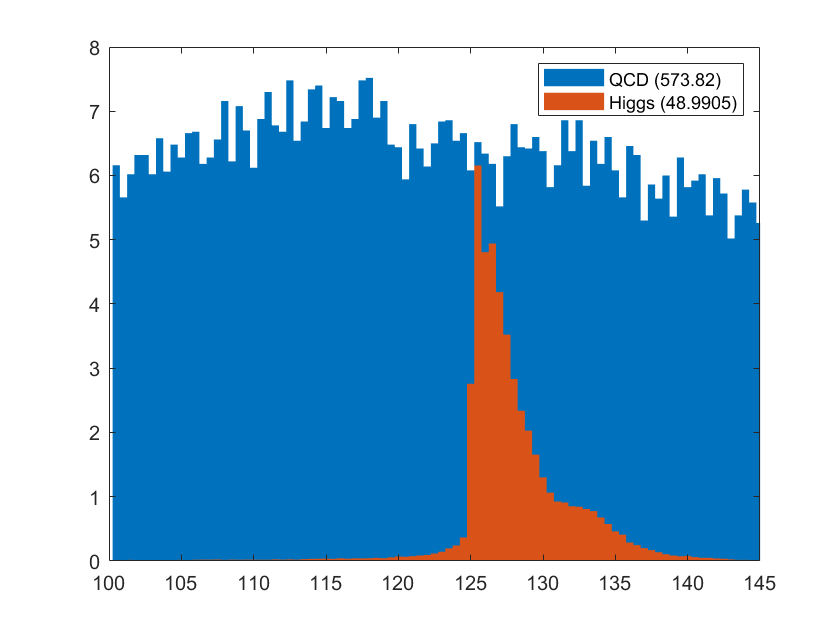


% re-plotting stacked histogram to see changes
figure("Visible","off");
x = lowercut:0.5:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 2.0451

The significance has increased. With this cut we remove nearly three-quarters of the QCD background while preserving almost all of our Higgs.

We will try moving inward towards 125, starting with cuts at 124 and 136.

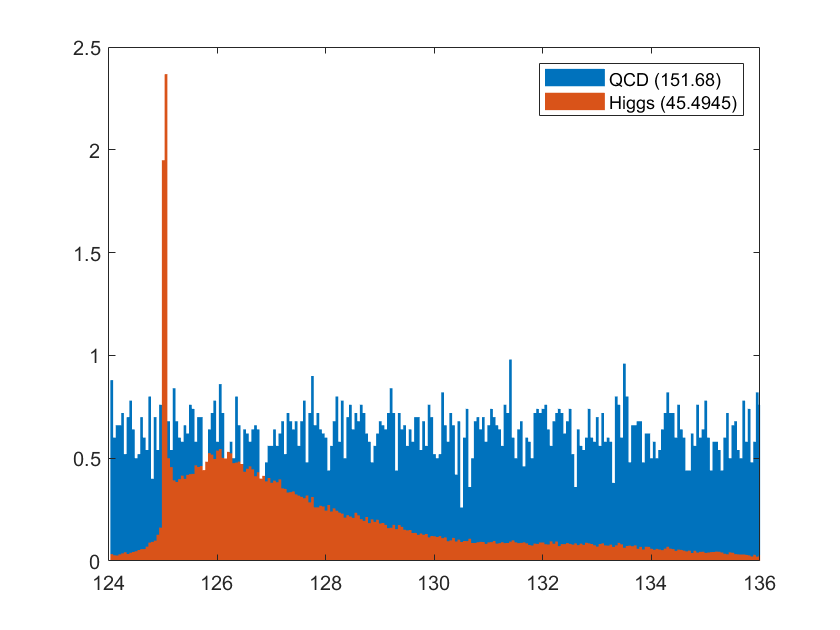

lowercut = 124;
uppercut = 136;
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;
% nhiggsbest = nhiggs; %
% nqcdbest = nqcd; %

% plotting again:
figure("Visible","off");
x = lowercut:0.05:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 3.6940

The significance has increased yet again. Over this range the Higgs compose nearly a third of the data we collect. 

We will now try cutting very, very close to 125.

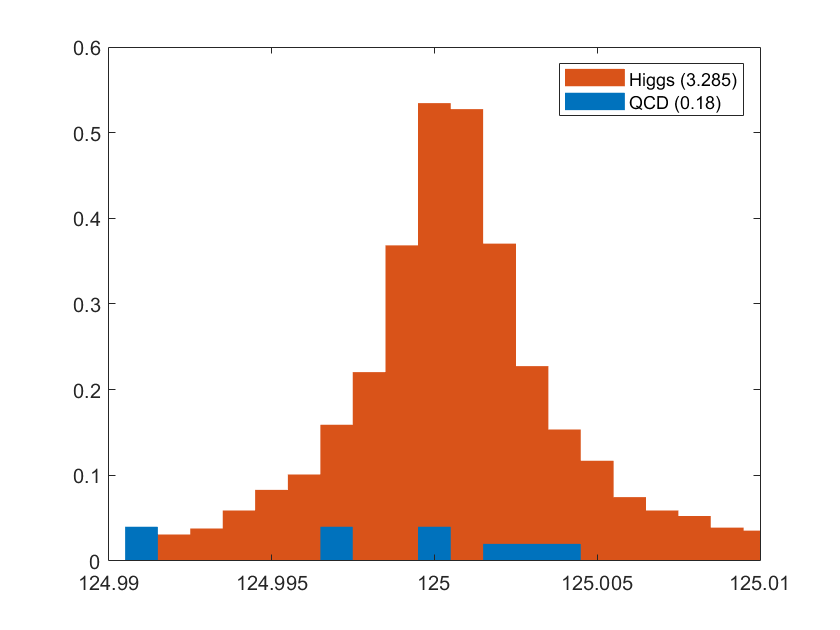

lowercut = 124.99;
uppercut = 125.01;
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;

figure("Visible","off");
x = lowercut:0.001:uppercut;
h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;
f1 = figure();
figure(f1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
hold on;
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
legend("Higgs (" + nhiggs + ")","QCD (" + nqcd + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 7.7428

Cut datasets with the highest significance are the ones trimmed closest to the mass value of 125. This may not mean anything because there are now gaps in the background distribution, so we're approaching the point where this counting method runs into trouble as it becomes possible to select cut regions with no background data within. We may need to rethink this approach and think purely in terms of distribution curve because the granularity is an issue. I was also told that cutting cutting just the mass will not result in significance greater than 1, so there may be something wrong with the method I am using.

I played around with some values and the highest I found was 7.7428 for when lower cut is 124.99 and upper cut is 125.01.

Nearly all of the QCD has been removed (this narrow slice of the QCD distribution contains very few of the 2000 expected). Most of the Higgs have also been lost. This granularity will create issues in Lab 8 because the sets of data have fewer points to work with, so we may risk losing information about the distribution if they happen to not fall often enough into the narrow range. Moving forward with this lab, I will try to preserve as much of the signal as I possibly can by selecting other features to cut around.

## Problem 3

Stacked histogram plots for the rest of the features.

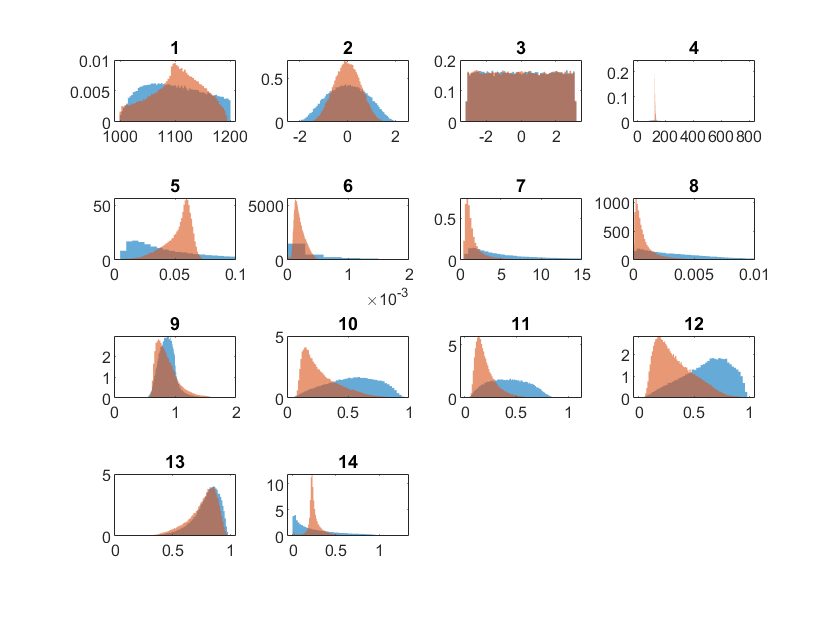

% just doing the 50 2000 thing makes them difficult to examine. I'm
% including this here with standard normalization to 1 to make it easier to find
% regions with little to no signal.
close all hidden;
for k = 1:14
    subplot(4,4,k);
    histogram(bgdata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(signaldata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    title("" + k);
    if k == 5
        xlim([0,0.1]);
    end
    if k == 6
        xlim([0,0.002]);
    end
    if k == 7
        xlim([0,15]);
    end
    if k == 8
        xlim([0,0.01]);
    end
    if k == 9
        xlim([0,2]);
    end
    if k == 10
        xlim([0,1]);
    end
    hold off;
end

Set A (without event selection):

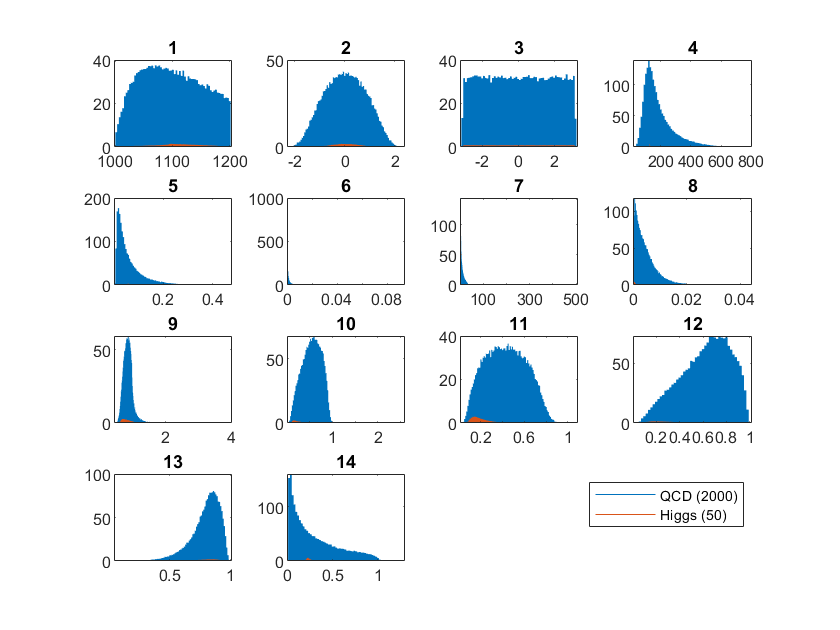

% these are with 50 2000 normalization
% subplot keeps this document easier to navigate but makes it difficult to
% find features with a glance. even without subplot, they are still
% difficult to examine without the normalization to 1.
close all hidden;
for k = 1:14
    signal = signaldata1(k,:);
    bg = bgdata1(k,:);
    subplot(4,4,k);
    h = histogram(signal,"Normalization","pdf");
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;  
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
    title("" + k);
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend('QCD (2000)','Higgs (50)');

It would appear, in conjuction with looking at the standard normal plots, that there are a number of "tails" that could be cut to improve significance, such as from the KtDeltaR (14) and other sharp feature signals against shallower background like the ECFs (5, 6, 7).

Set B (with optimal mass cuts):

% running into issues with making cuts easily when dealing with full matrix
lowercut = 124;
uppercut = 136;
signal = signaldata1(4,:);
bg = bgdata1(4,:);
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);
nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;
nhiggs/sqrt(nqcd)

ans = 3.6940

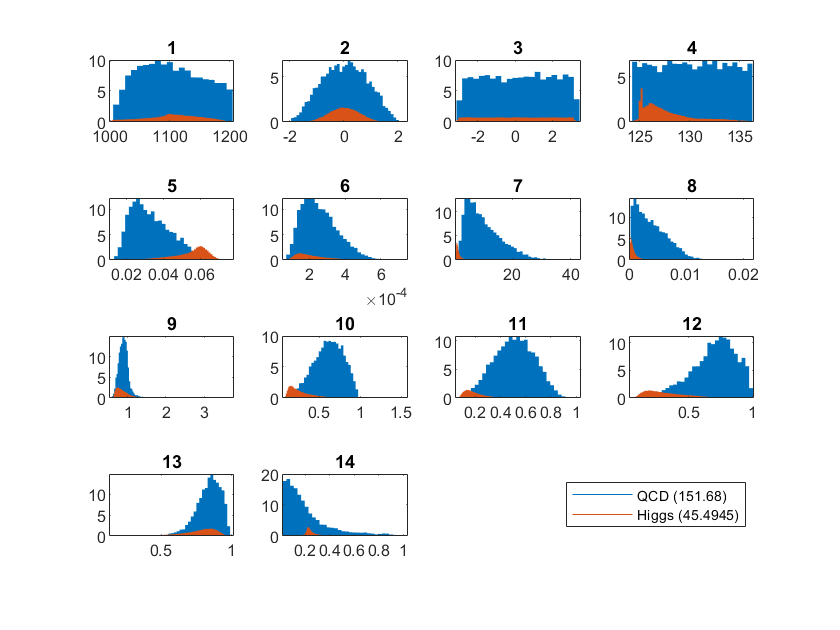


newcutsignal = signaldata1;
newcutbg = bgdata1;
for k = 1:100000
    if newcutsignal(4,k) > uppercut || newcutsignal(4,k) < lowercut
        newcutsignal(:,k) = nan;
    end
    if newcutbg(4,k) > uppercut || newcutbg(4,k) < lowercut
        newcutbg(:,k) = nan;
    end
end
% nhiggs = nhiggsbest;
% nqcd = nqcdbest;
close all hidden;
for k = 1:14
    signal = newcutsignal(k,:);
    bg = newcutbg(k,:);
    subplot(4,4,k);
    h = histogram(signal,"Normalization","pdf");
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;  
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
    title("" + k);
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");

There looks to be a number of good places to get cuts, now including 5,8,11, and 12. 14 and 7 still look good.

OLD TEXT: Running into the same issues when things are too small. Not enough background to work with. Some plots show background centered away which can be cut further while preserving much of the true Higgs distribution, but at this point removing more gets us closer to removing the background entirely which doesn't make sense and would cause division by zero for our n over root n calculation we've been doing. Something is clearly wrong with this approach.

## Problem 4

OLD TEXT: Using multiple features may not be necessary because when we've cut the background down to such a narrow region around mass 125 MeV the events are very likely (7.5-ish) to be the signal.

I will make cuts for additional features to try to improve significance. I'll start by cutting (7), the 2-to 3-point ECF.

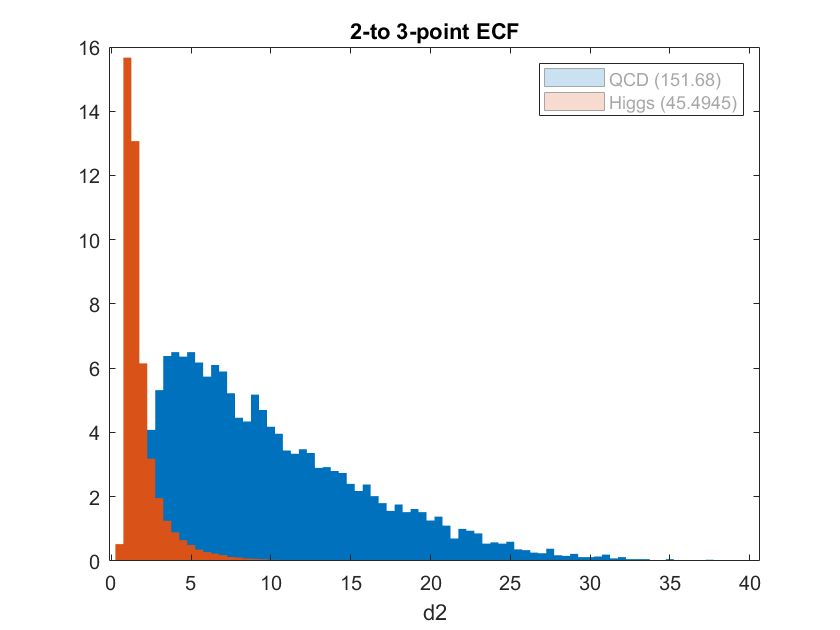

close all hidden;
signal = newcutsignal(7,:);
bg = newcutbg(7,:);
x = 0:0.5:40;
h = histogram(signal,x,"Normalization","pdf");
set(h,'Visible','off');
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(bg,x,"Normalization","pdf");
set(h2,'Visible','off');
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;  
b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
title("2-to 3-point ECF");
xlabel("d2");
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
hold off;

I'll try cutting everything above the value 4.

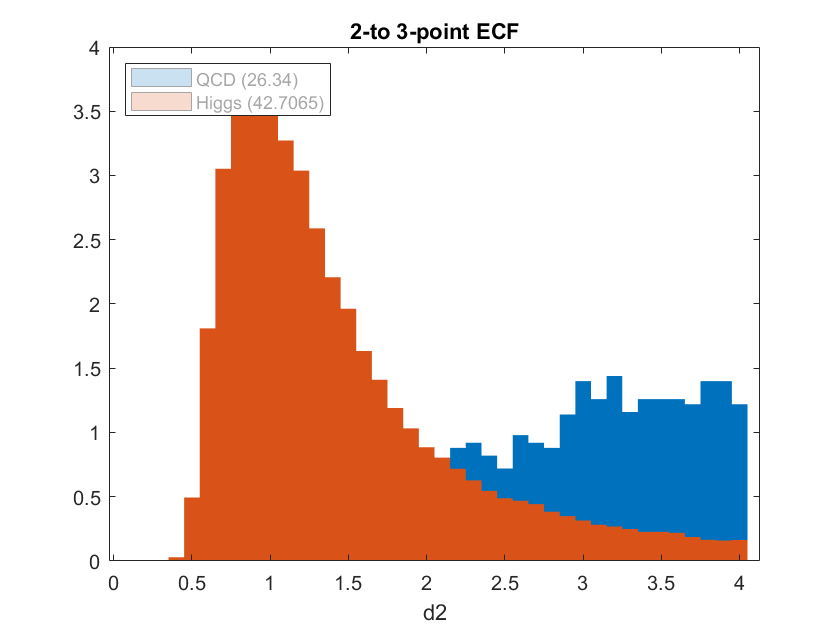

lowercut = 0;
uppercut = 4;
ncs1 = newcutsignal;
ncb1 = newcutbg;
for k = 1:100000
    if ncs1(7,k) > uppercut || ncs1(7,k) < lowercut
        ncs1(:,k) = nan;
    end
    if ncb1(7,k) > uppercut || ncb1(7,k) < lowercut
        ncb1(:,k) = nan;
    end
end

signal = ncs1(7,:);
bg = ncb1(7,:);
numelsignal = length(signal(~isnan(signal)));
numelbg = length(bg(~isnan(bg)));
nhiggs = numelsignal/100000*50;
nqcd = numelbg/100000*2000;

x = 0:0.1:4; % required to make graph scale right
h = histogram(signal,x,"Normalization","pdf");
set(h,'Visible','off');
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(bg,x,"Normalization","pdf");
set(h2,'Visible','off');
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;  
b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
title("2-to 3-point ECF");
xlabel("d2");
legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")","Location","northwest");
hold off;

nhiggs/sqrt(nqcd)

ans = 8.3212

Doing this has produced a significance value greater than what we were getting just doing the mass cuts, while also preserving most of the Higgs data. This can be continued for other features to keep improving significance (TO DO).

Lab partners should reach the same conclusion: making cuts using multiple features can greatly improve significance. *Add more info, pending results from lab partners.

## Problem 5 - Bonus (optional)

2d scatter plot between top two most discriminating features (TO DO).